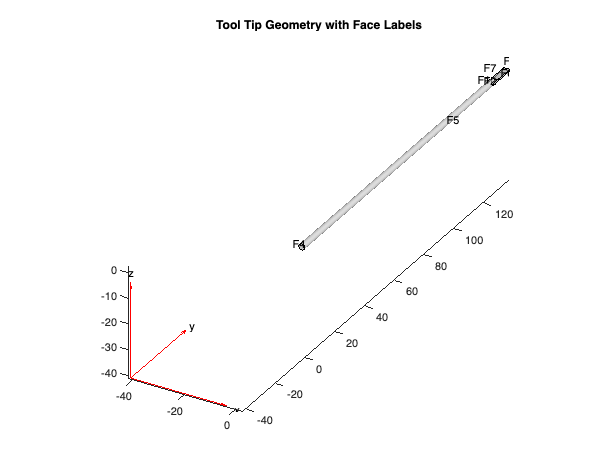

% Load geometry and create structural model
model = femodel(AnalysisType="structuralStatic", Geometry="electrode_MATLAB_test.STL");

% Visualize geometry with face labels
figure
pdegplot(model, FaceLabels="on", FaceAlpha=0.5)
title("Tool Tip Geometry with Face Labels")

targetTempK = 200 + 273.15;


% Generate mesh
model = generateMesh(model, Hmax=0.2, GeometricOrder="linear");

E = 200E9;        % Young's modulus in Pa
nu = 0.28;        % Poisson's ratio
CTE = 11.0E-6;    % Thermal expansion in 1/K
k = 24;           % Thermal conductivity in W/m·K
h = 1;              % Convection coefficient in W/(m²·K)
% Assign structural properties 
model.MaterialProperties = materialProperties(YoungsModulus=E, PoissonsRatio=nu, CTE=CTE);

% Fix the distal tip (face 3) to anchor the model 
model.FaceBC(3) = faceBC(Constraint="fixed"); 

% Switch to thermal analysis 
model.AnalysisType = "thermalSteady"; 
model.MaterialProperties = materialProperties(ThermalConductivity=k);

heatFlux = 1e3;  % Initial guess in W/m^2
tolerance = 5;
maxIter = 20;

for i = 1:maxIter
    model.FaceLoad(:) = [];  % Clear previous loads
    model.FaceLoad(4) = faceLoad(Heat=heatFlux);
    %Add Convection cooling to non-active faces
    model.FaceLoad(3) = faceLoad(ConvectionCoefficient=h, AmbientTemperature=25);

    Rt = solve(model);
    tipNodes = findNodes(Rt.Mesh, "region", "Face", 3);
    tipTemp = max(Rt.Temperature(tipNodes));
    if abs(tipTemp - targetTempK) < tolerance
        break
    end
    heatFlux = heatFlux * (1 + 0.1 * sign(targetTempK - tipTemp));
end


fprintf("Required heat flux to reach 200°C at tip: %.2e W/m²\n", heatFlux);

Required heat flux to reach 200°C at tip: 7.94e+02 W/m²


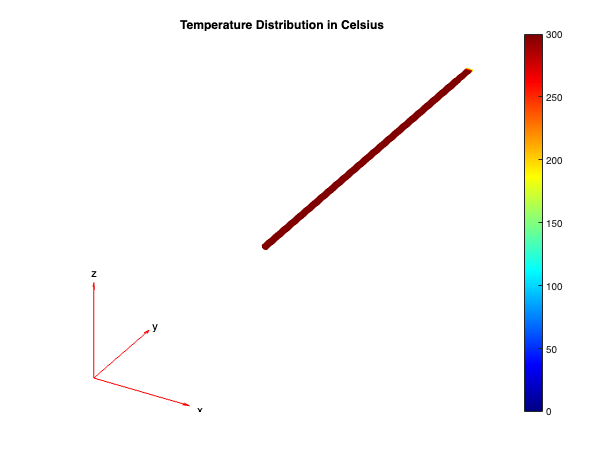


% Convert temperature to Celsius
tempC = Rt.Temperature - 273.15;

% Plot temperature distribution in Celsius
figure
pdeplot3D(Rt.Mesh, ColorMapData=tempC)
title("Temperature Distribution in Celsius")
xlabel("X (m)")
ylabel("Y (m)")
zlabel("Z (m)")
colorbar
clim([0, 300])  % Adjust range based on expected temperature